## **Example 1: birth-death process**

We wish to run the SSA for the reaction network


$$
\emptyset \rightarrow X \quad \text{with rate} \; k_1 \\
X \rightarrow \emptyset \quad \text{with rate} \; k_2
$$


**Step 1: Define the reaction network object**

stoichiometricMatrix=[1,-1]; %net changes in each reaction
Omega=1; %container volume
propensityFunctions= @(x) [Omega,x]; %mass-action kinetics
rateVector=[100,2]; %[k1,k2]
%calling constructor of reaction network object
rxn= RxnNet(stoichiometricMatrix,rateVector,propensityFunctions);

**Step 2: Set simulation conditions and run simulation**

extinction=false; % No absorbing boundary
timeVector=0:0.2:10000;
initialNumbers=50;%initial molecule number
%run simlation
tic
trajectories=rxn.SSA(timeVector,initialNumbers,extinction);
toc

Elapsed time is 4.748048 seconds.


**Step 3: Compare with theoretical solution**

Since the reaction network obeys detailed balance, the solution to the chemical master equation is a poisson distribution

n=(min(trajectories(:,1)):max(trajectories(:,1)));
Ptheo=exp(-rateVector(1)/rateVector(2))./factorial(n) .* (rateVector(1)/rateVector(2)).^n;


**Step 4: Plot**

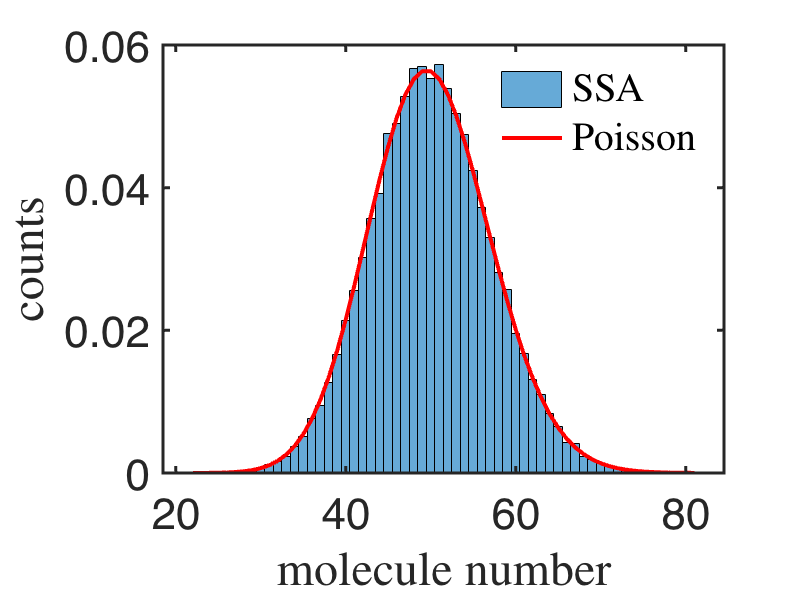

figure,histogram(trajectories(:,1),'BinEdges',(min(trajectories(:,1))-0.5):(max(trajectories(:,1))+0.5),'Normalization','pdf'), hold on, 
plot(n,Ptheo,'r','LineWidth',2)

ax=gca; ax.FontSize=22; ax.LineWidth=1.5;
xlabel('molecule number','FontSize',24,'Interpreter','latex');
ylabel('counts','FontSize',24,'Interpreter','latex');
legend('SSA','Poisson','FontSize',20,'Interpreter','latex');
legend boxoff